## Plotting Time-Domain Signals

a = 1;
f = 1000;
phi = 0;
fs = 44.1e3;
T_s = 0.01;

sin1kHz = generate_sinusoid(a, f, phi, fs, T_s);

[RecordedSignal, fs] = audioread("RecordingWhistle.wav");
t_recorded = (0:length(RecordedSignal)-1)/fs;

t_recorded = t_recorded-0.1510;

length(RecordedSignal)/fs

ans = 0.5005

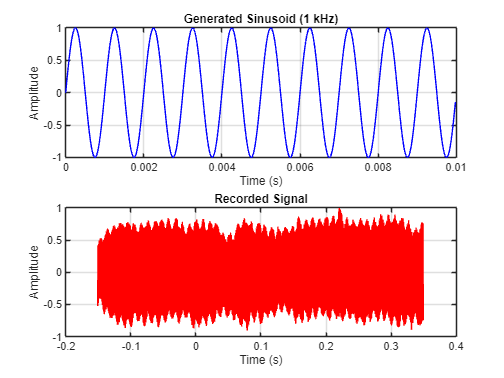


% Plot the generated sinusoid
figure;
subplot(2,1,1);  % Create a subplot for separate plotting
plot(sin1kHz.time_vector, sin1kHz.signal, 'b');  % Plot sinusoid in blue
xlabel('Time (s)');
ylabel('Amplitude');
title('Generated Sinusoid (1 kHz)');
grid on;

% Plot the recorded signal

idx = (t_recorded >= 0 & t_recorded <= (T_s)-1/fs);

subplot(2,1,2);  % Create a second subplot
plot(t_recorded, RecordedSignal, 'r');  % Plot recorded signal in red
xlabel('Time (s)');
ylabel('Amplitude');
title('Recorded Signal');
grid on;

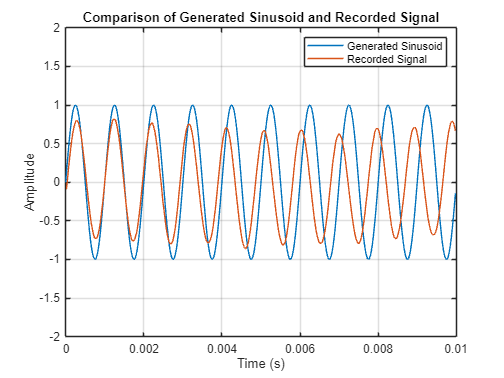


% For better comparison, you can also plot both on the same graph if they are time-aligned
figure;
plot(sin1kHz.time_vector, sin1kHz.signal, 'DisplayName', 'Generated Sinusoid (1 kHz)'); hold on;  % Plot sinusoid in blue
plot(t_recorded(idx), RecordedSignal(idx));  % Plot recorded signal in red
xlabel('Time (s)');
ylabel('Amplitude');
title('Comparison of Generated Sinusoid and Recorded Signal');
ylim([-2 2])
legend('Generated Sinusoid', 'Recorded Signal');
grid on;

% Adjust the parameters for the generated sinusoid
a = 1;              % Amplitude
f = 1000;           % Frequency in Hz (1 kHz)
phi = 0;           % Phase in radians
fs = 6000;         % Adjusted sampling frequency to achieve 2 Hz resolution
T_s = 0.5;         % Duration in seconds to obtain sufficient data length

% Generate the sinusoid using the custom function
sin1kHz = generate_sinusoid(a, f, phi, fs, T_s);

% Determine the number of samples for the recorded signal
% Step 2: Define the time range in seconds
start_time = 0;  % Start time in seconds
end_time = 0.5;    % End time in seconds
fs_recorded = 44100; % We Know the sampling frequency
% Step 3: Calculate the sample indices
start_sample = round(start_time * fs_recorded) + 1; % Convert to sample index
end_sample = round(end_time * fs_recorded);          % Convert to sample index

% Load the recorded signal from a .wav file
[RecordedSignal, fs_recorded] = audioread("RecordingWhistle.wav", [start_sample, end_sample]);

%[RecordedSignal, fs_recorded] = audioread("RecordedSignalFull.wav", [1 fs_recorded*T_s]);

% Check if the audio is stereo
if size(RecordedSignal, 2) > 1
    % If stereo, select the first channel (left channel)
    RecordedSignal = RecordedSignal(:, 1);
end

% Downsample recorded signal
recorded_signal_downsampled = resample(RecordedSignal, fs, fs_recorded);

% Compute the spectrum for the generated sinusoid
sin1kHz_spectrum = make_spectrum(sin1kHz.signal, fs);

hanning_window = hanning(length(RecordedSignal));
windowed_recorded_signal = RecordedSignal .* hanning_window;

% Compute the spectrum for the recorded signal
recorded_spectrum = make_spectrum(RecordedSignal, fs_recorded);

% Compute the dB values
dB_sin1kHz = 20 * log10(abs(sin1kHz_spectrum.Y/max(abs(sin1kHz_spectrum.Y))));
dB_recorded = 20 * log10(abs(recorded_spectrum.Y/max(abs(sin1kHz_spectrum.Y))));
%dB_recorded = 20 * log10(abs(recorded_spectrum.Y));
% Set threshold for the sinusoid spectrum
threshold = -20;
dB_sin1kHz(dB_sin1kHz < threshold) = NaN;
%Find Max dB
fprintf("Max dB: %2.3f\n", max(dB_recorded))

Max dB: -9.791


% Find at which frequencies we have max dB
index =  find( dB_recorded == max(dB_recorded) );
fprintf("Max dB at the frequencies: {%d Hz, %d Hz}", recorded_spectrum.freq(index))

Max dB at the frequencies: {-1042 Hz, 1042 Hz}

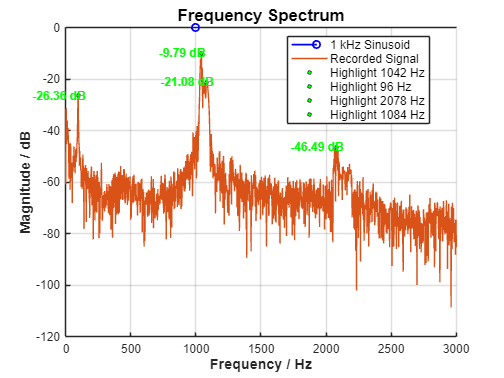


% ---------------------------------------------------FIGURE CREATION----------------------------------------------------------------------------------------------------%

% Create the figure
figure;
hold on;  % Keep the current figure to add multiple plots

% Plotting the generated sinusoid using lines for better visibility
stem(sin1kHz_spectrum.freq, dB_sin1kHz, 'b-', 'LineWidth', 1.5, 'DisplayName', '1 kHz Sinusoid');

% Create a scatter plot for the recorded signal with transparency
plot(recorded_spectrum.freq, dB_recorded, 'DisplayName','Recorded Signal');
%stem(recorded_spectrum.freq, dB_recorded, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Recorded Signal');



% Frequency points to highlight:
highlight_freqs = [1042, 96, 2078, 1084];

%Plot the points and add text, for each frequency we want to highlight
for freq = highlight_freqs
    % Find the closest index to the specified frequency
    [~, idx] = min(abs(recorded_spectrum.freq - freq));
    
    % Plot a marker at the highlighted frequency
    plot(recorded_spectrum.freq(idx), dB_recorded(idx), 'ko', 'MarkerSize', 3, ...
        'MarkerFaceColor', 'g', 'DisplayName', sprintf('Highlight %d Hz', freq));
    
    % Get the dB value at the highlighted frequency
    valueAtFreq = dB_recorded(idx);
    
    % Add custom text label near the marker
    text(recorded_spectrum.freq(idx) - 150, valueAtFreq, sprintf('%.2f dB', valueAtFreq), ...
        'Color', 'g', 'FontSize', 10, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
end

% Enhance plot appearance
xlabel('Frequency / Hz', 'FontWeight', 'bold', 'FontSize', 12);
ylabel('Magnitude / dB', 'FontWeight', 'bold', 'FontSize', 12);
xlim([0 3000]);
grid on;  % Add grid for better readability

% Add legend
legend('Location', 'best', 'FontSize', 10);


% Title
title('Frequency Spectrum', 'FontWeight', 'bold', 'FontSize', 14);

% Adjust the y-axis limits for better visibility
%ylim([-100 10]);  % Adjust as necessary to focus on the relevant range

hold off;  % Release the hold on the current figure